# CLO

Copyright © 2025 Michael Robbins. Licensed under the Apache License 2.0 (the "License"); you may not use this file except in compliance with the License. Obtain a copy at http://www.apache.org/licenses/LICENSE-2.0. Distributed on an "AS IS" BASIS, WITHOUT WARRANTIES OR CONDITIONS OF ANY KIND, either express or implied. See the License for specific terms and limitations.

Robbins_Copyright2025_AQAM_Environment;

## Comprehensive CLO Model Simulation with Empirical Parameter Derivation, Triggers, Overcollateralization, Yield Enhancement, and Data-Driven Asset Correlation Calibration

This script integrates:

- A raw data simulation ("cracking the tape") to derive empirical default (PD)  and prepayment (CPR) probabilities from heterogeneous loan performance using  a time-to-event model.

- Derivation of an asset correlation parameter (rho) from the tape data using a simple Vasicek inversion approach.

- A single-period Gaussian copula simulation for correlated defaults, waterfall allocation, and trigger events. The default probability for the copula is derived from the tape, and the asset correlation is set to the data-derived rho.

- A multi-period simulation using enhanced transition matrices derived from simulated loan performance.

- Overcollateralization (OC) triggers are implemented by comparing the OC ratio, computed as (Collateral - Loss) / Debt, to a threshold.

- Yield enhancement is added for the equity tranche if the OC ratio exceeds a high‐performance threshold.

Assumptions:

- The portfolio consists of 'numLoans' loans with heterogeneous characteristics.

- Each loan is assigned its own annual default probability (PD) and constant prepayment rate (CPR).

- A one-factor Gaussian copula model is used for initial default correlation.

- Loss given default (LGD) is calculated as (1 - recoveryRate).

- A trigger is activated if the normalized loss exceeds 'trigger_threshold' and/or if the OC ratio falls below a set threshold.

- "Cracking the tape" is represented by simulating raw loan performance data using a time-to-event (hazard rate) approach.

- Yield enhancement for the equity tranche is provided if the OC ratio exceeds a high threshold.

clear; clc; close all;

Simulation constants

numLoans = 100;            % Number of loans in the portfolio (for later simulation)
N_tape = 10000;            % Number of simulated loans for tape analysis
numSim = 100000;           % Number of Monte Carlo simulations for the copula model
T = 5;                     % Number of periods (e.g., years)
numSimMulti = 50000;       % Number of simulations for the multi-period model

Copula initialization

trancheLosses_copula = zeros(numSim, 1);
triggerEvents_copula = zeros(numSim, 1);  % Indicator for normalized loss trigger
ocTrigger_copula = zeros(numSim, 1);        % Indicator for overcollateralization trigger
yieldEnhancement_copula = zeros(numSim, 1);   % Yield enhancement for the equity tranche

Loan initialization

PD_tape = zeros(N_tape,1);
CPR_tape = zeros(N_tape,1);
raw_states = zeros(N_tape,1);
finalDefaults = zeros(numSimMulti,1);
finalPrepaids = zeros(numSimMulti,1);
triggerEvents_multi = zeros(numSimMulti, 1);  % Trigger for normalized loss
ocTrigger_multi = zeros(numSimMulti, 1);        % Overcollateralization trigger
yieldEnhancement_multi = zeros(numSimMulti,1);   % Yield enhancement for equity tranche

### 1. Constants

exposure = 1;               % Notional exposure per loan (normalized)
recoveryRate = 0.40;         % Recovery rate (thus, LGD = 1 - recoveryRate)
overcollateralization = 0.9; % Assume outstanding debt is 90% of maxTotalLoss (i.e. overcollateralized structure)
OC_threshold = 1.2;        % Minimum acceptable OC ratio trigger (if OC < this, trigger fires)
OC_threshold_high = 1.5;   % OC ratio above which yield enhancement is paid (for equity tranche)
k_yield = 0.05;            % Scaling factor (yield enhancement per unit OC ratio above threshold)
a1 = 0.03;                 % Waterfall attachment points (normalized) Equity tranche cap
a2 = 0.07;                 % Waterfall attachment points (normalized) Combined equity + mezzanine tranche cap
trigger_threshold = 0.08;  % Trigger threshold for normalized loss (simple trigger)

### 2. Simulating Raw Loan Performance Data ("Cracking the Tape")

PD_tape  = 0.01 + (0.05-0.01)*betarnd(2,2, N_tape, 1);  % Generate PD and CPR for each loan (as column vectors)
CPR_tape = 0.02 + (0.08-0.02)*betarnd(2,2, N_tape, 1);
TTD = exprnd(1./(-log(1-PD_tape))); % Use a time-to-event approach for each loan over one year to
TTP = exprnd(1./(-log(1-CPR_tape))); %     compute TTD and TTP for all loans using hazard rates
event_idx = (min(TTD, TTP) < 1); % Identify indices where an event occurs (min(TTD,TTP) < 1)
raw_states(event_idx & (TTD < TTP)) = 2; % For loans with an event, assign state 2 (default) if TTD occurs first,
raw_states(event_idx & (TTD >= TTP))  = 3; % and state 3 (prepayment) if TTP occurs first or simultaneously.

Derive empirical transition probabilities from tape data

p_default_emp = sum(raw_states == 2) / N_tape;     % Active -> Active
p_prepay_emp  = sum(raw_states == 3) / N_tape;     % Active -> Default
p_active_emp  = 1 - p_default_emp - p_prepay_emp;  % Active -> Prepaid
P_empirical = [p_active_emp, p_default_emp, p_prepay_emp;0,1,0;0,0,1]; % aggregated (empirical) transition matrix (absorbing states)

### 3. Estimate Asset Correlation (rho) for the Gaussian Copula Simulation from Tape Data using a simplified Vasicek inversion

rho_est = max(min(1-((norminv(mean(PD_tape))/norminv(p_default_emp))^2 ),1),0);

### 4. Simulate heterogeneous loan characteristics for the portfolio: Each loan gets its own annual PD and CPR.

PD_vec = 0.01 + (0.05 - 0.01) * betarnd(2, 2, numLoans, 1);  % Individual default probabilities
CPR_vec = 0.02 + (0.08 - 0.02) * betarnd(2, 2, numLoans, 1); % Individual constant prepayment rates

### 5. Gaussian Copula Simulation with Waterfall, Trigger, Overcollateralization, and Yield Enhancement (Single-Period)

loanLoss = exposure * (1 - recoveryRate);
maxTotalLoss = numLoans * loanLoss;
idioFactors = randn(numLoans, numSim); % Generate idiosyncratic risk for each loan in all simulations  
assetValues = sqrt(rho_est)*ones(numLoans,1)*randn(numSim, 1).' + sqrt(1 - rho_est)*idioFactors; % Compute asset values using the Gaussian copula model for all simulations  
defaults = assetValues <  norminv(p_default_emp, 0, 1); % Determine defaults for each loan in each simulation (asset value < default threshold)  
portfolioLoss = sum(defaults, 1) * loanLoss; % Calculate portfolio loss (absolute and normalized) for each simulation  
L_f = portfolioLoss / maxTotalLoss;  % Normalized loss fraction for each simulation  
equityLoss = min(L_f, a1); % Waterfall allocation for equity tranche for each simulation  
mezzanineLoss = min(max(L_f - a1, 0), (a2 - a1)); % Waterfall allocation for mezzanine tranche for each simulation  
seniorLoss = max(L_f - a2, 0); % Waterfall allocation for senior tranche for each simulation  
trancheLosses_copula = equityLoss + mezzanineLoss + seniorLoss; % Record overall allocated loss for each simulation  
triggerEvents_copula = L_f > trigger_threshold; % Flag trigger event based on normalized loss for each simulation  
OC_ratio = (maxTotalLoss - portfolioLoss) / (overcollateralization*maxTotalLoss); % Calculate Overcollateralization (OC) ratio where maxTotalLoss = Collateral for each simulation  
ocTrigger_copula = OC_ratio < OC_threshold; % Determine OC trigger events for each simulation  
yieldEnhancement_copula = max(0, k_yield * (OC_ratio - OC_threshold_high)); % Calculate yield enhancement for the equity tranche if OC_ratio > threshold for each simulation  

### 6. Multi-Period Simulation with Heterogeneous Loan Characteristics, Enhanced Transition Matrices,  Active=1, Default=2, Prepaid=3

TTD_param = 1./(-log(1 - PD_vec)); % Parameter for time-to-default for each loan (numLoans x 1)  
TTP_param = 1./(-log(1 - CPR_vec)); % Parameter for time-to-prepayment for each loan (numLoans x 1)  
TTD = exprnd(repmat(TTD_param, 1, numSimMulti)); % Simulate time-to-default for each loan in each simulation (numLoans x numSimMulti)  
TTP = exprnd(repmat(TTP_param, 1, numSimMulti)); % Simulate time-to-prepayment for each loan in each simulation (numLoans x numSimMulti)  
eventTime = min(TTD, TTP); % Compute event time using competing risks (numLoans x numSimMulti)  
defaults_count = sum((eventTime <= T) & (TTD < TTP), 1); % Count defaults per simulation (1 x numSimMulti)  
prepaids_count = sum((eventTime <= T) & (TTD >= TTP), 1); % Count prepayments per simulation (1 x numSimMulti)  
finalDefaults = defaults_count; % Record final defaults per simulation (1 x numSimMulti)  
finalPrepaids = prepaids_count; % Record final prepaids per simulation (1 x numSimMulti)  
L_f_multi = (defaults_count * loanLoss) / maxTotalLoss; % Compute normalized loss for multi-period simulation (only defaults incur loss) (1 x numSimMulti)  
triggerEvents_multi = L_f_multi > trigger_threshold; % Flag trigger events based on normalized loss for each simulation (1 x numSimMulti)  
portfolioLoss_multi_sim = defaults_count * loanLoss; % Compute portfolio loss for each simulation from defaults (1 x numSimMulti)  
OC_ratio_multi = (maxTotalLoss - portfolioLoss_multi_sim) / (overcollateralization * maxTotalLoss); % Calculate Overcollateralization (OC) ratio for each simulation (1 x numSimMulti)  
ocTrigger_multi = OC_ratio_multi < OC_threshold; % Determine OC trigger events for each simulation (1 x numSimMulti)  
yieldEnhancement_multi = max(0, k_yield * (OC_ratio_multi - OC_threshold_high)); % Compute yield enhancement for equity tranche for each simulation (1 x numSimMulti)  
avgYieldEnhancement_multi = mean(yieldEnhancement_multi); % Average Yield Enhancement (Equity Tranche, Multi-Period)  
cumulativeDefaultRate = mean(finalDefaults) / numLoans; % Cumulative default rate across simulations  
cumulativePrepayRate = mean(finalPrepaids) / numLoans; % Cumulative prepayment rate across simulations  
portfolioLoss_multi = mean(finalDefaults) * loanLoss; % Average portfolio loss from defaults across simulations  
L_f_multi_avg = portfolioLoss_multi / maxTotalLoss; % Normalized average portfolio loss  

Waterfall allocation using multi-period losses:

equityLoss_multi = min(L_f_multi_avg, a1); % Expected Equity Tranche Loss
mezzanineLoss_multi = min(max(L_f_multi_avg - a1, 0), (a2 - a1)); % Expected Mezzanine Tranche Loss
seniorLoss_multi = max(L_f_multi_avg - a2, 0); % Expected Senior Tranche Loss
triggerFrequency_multi = mean(triggerEvents_multi); % Trigger Frequency (Loss > trigger_threshold)
ocTriggerFrequency_multi = mean(ocTrigger_multi); % Overcollateralization Trigger Frequency (OC ratio < OC_threshold)
losses_multi = finalDefaults * loanLoss / maxTotalLoss;

## 7. Visualization: Compare Loss Distributions

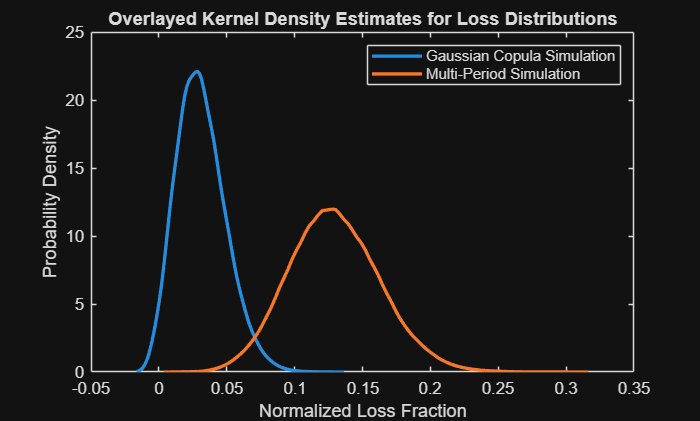

[x1, f1] = ksdensity(trancheLosses_copula,'Bandwidth',0.0055);
[x2, f2] = ksdensity(losses_multi,'Bandwidth',0.0055);
plot(f1,x1,f2,x2,'LineWidth', 2);
xlabel('Normalized Loss Fraction');
ylabel('Probability Density');
title('Overlayed Kernel Density Estimates for Loss Distributions');
legend('Gaussian Copula Simulation', 'Multi-Period Simulation');

%% Plotting Charts for CLO Analysis
% This script produces several charts to help analysts visualize the risk,
% return, and cash flow profiles of CLOs. The charts include:
% 1. Cash Flow Waterfall Chart
% 2. Sensitivity and Scenario Analysis Chart (PD vs. Expected Loss)
% 3. Monte Carlo Simulation Graph (Cumulative Distribution of Losses)
% 4. Spread and Yield Ladder Chart
% 5. Cumulative Loss and Default Rate Curve
% 6. Recovery Rate Sensitivity Chart
% 7. Duration and Convexity Analysis Charts
% 8. Asset/Collateral Performance Graph (PD vs. CPR)
% 9. Rating Transition/Migration Heat Map


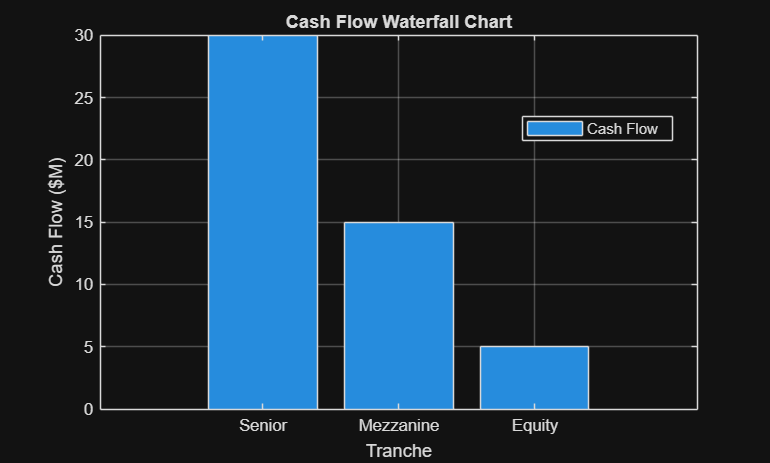

%% Chart 1: Cash Flow Waterfall Chart
% For illustration, we create sample cash flow data for three tranches.
% Assume total cash flow is distributed among Senior, Mezzanine, and Equity.
senior_cf = 30;
mezzanine_cf = 15;
equity_cf = 5;
total_cf = senior_cf + mezzanine_cf + equity_cf;

% Use a simple waterfall-like bar chart
figure;
bar([senior_cf, mezzanine_cf, equity_cf],'stacked');
title('Cash Flow Waterfall Chart');
xlabel('Tranche');
ylabel('Cash Flow ($M)');
set(gca, 'XTickLabel', {'Senior','Mezzanine','Equity'});
legend({'Cash Flow'}, 'Location','Best');
grid on;

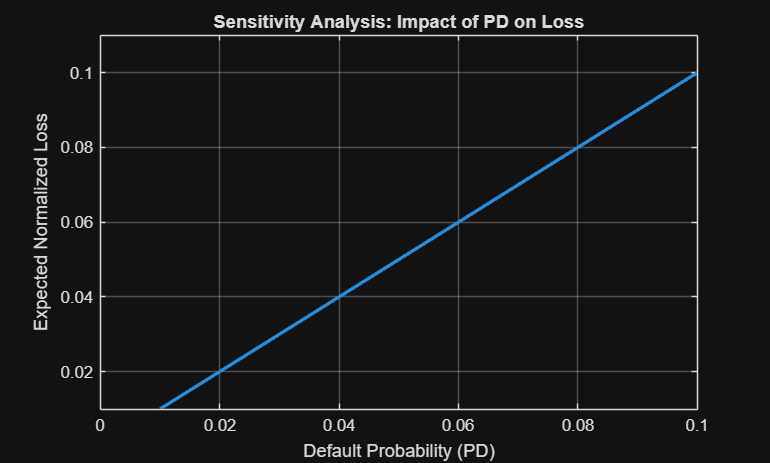

%% Chart 2: Sensitivity and Scenario Analysis Chart
% Analyze the sensitivity of expected normalized loss to changes in PD.
PD_range = linspace(0.01, 0.10, 50);
% For illustration, assume a simple linear relationship: 
expected_loss = PD_range;  % (In practice, run scenarios through your model)
figure;
plot(PD_range, expected_loss, 'LineWidth',2);
xlabel('Default Probability (PD)');
ylabel('Expected Normalized Loss');
title('Sensitivity Analysis: Impact of PD on Loss');
grid on;

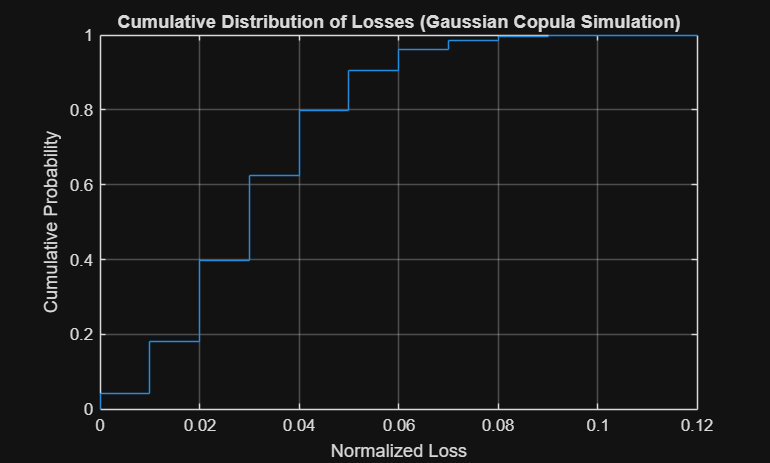

%% Chart 3: Monte Carlo Simulation Graph
% Use the empirical loss data from the single-period Gaussian Copula simulation.
% (Assume "trancheLosses_copula" was computed in the simulation code.)
figure;
ecdf(trancheLosses_copula);
xlabel('Normalized Loss');
ylabel('Cumulative Probability');
title('Cumulative Distribution of Losses (Gaussian Copula Simulation)');
grid on;

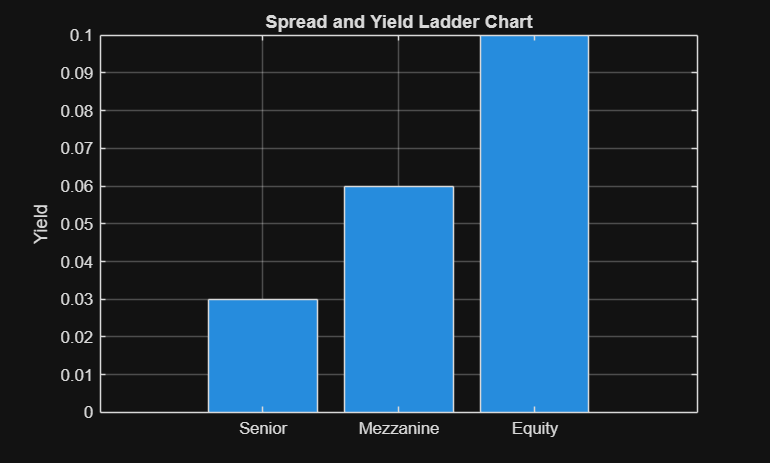

%% Chart 4: Spread and Yield Ladder Chart
% Assume base yields for each tranche; add yield enhancement for Equity.
tranche_names = {'Senior','Mezzanine','Equity'};
base_yields = [0.03, 0.06, 0.10];  % Example base yields (3%, 6%, 10%)
% For demonstration, add the average yield enhancement from the copula simulation.
% (Assume avgYieldEnhancement_copula was computed.)
equity_yield = base_yields(3) + avgYieldEnhancement_multi;
yields = [base_yields(1), base_yields(2), equity_yield];
figure;
bar(yields);
set(gca, 'XTickLabel', tranche_names);
ylabel('Yield');
title('Spread and Yield Ladder Chart');
grid on;

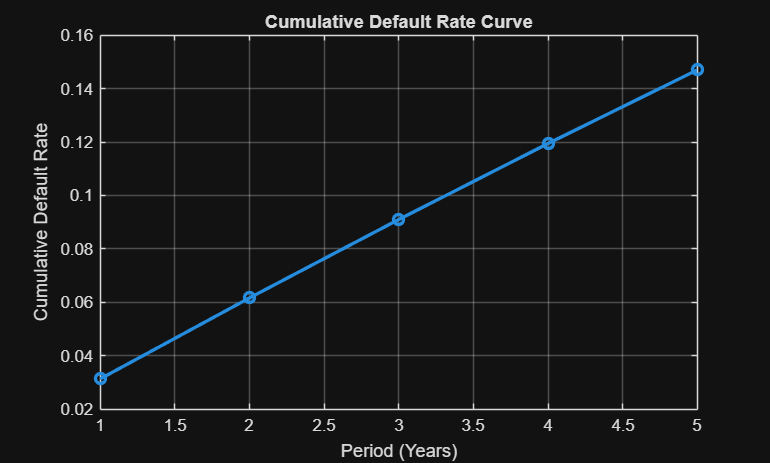

%% Chart 5: Cumulative Loss and Default Rate Curve
% Simulate a cumulative default rate curve using the average PD from the multi-period simulation.
% (Assume PD_vec was generated for each loan.)
T = 5;  % Number of periods (years)
T_vec = 1:T;
avg_PD = mean(PD_vec);
% Cumulative default rate: 1 - (1-PD)^t for t = 1,...,T.
cum_default = 1 - (1 - avg_PD).^T_vec;
figure;
plot(T_vec, cum_default, '-o','LineWidth',2);
xlabel('Period (Years)');
ylabel('Cumulative Default Rate');
title('Cumulative Default Rate Curve');
grid on;

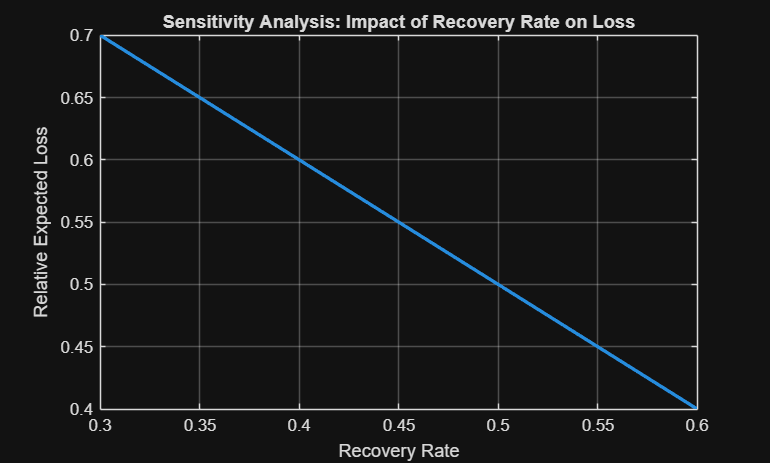

%% Chart 6: Recovery Rate Sensitivity Chart
% Plot the effect of varying recovery rate on expected loss.
recovery_range = linspace(0.3, 0.6, 50);
% Assume expected loss is inversely proportional to recovery (simplified).
expected_loss_recovery = 1 - recovery_range;  
figure;
plot(recovery_range, expected_loss_recovery, 'LineWidth',2);
xlabel('Recovery Rate');
ylabel('Relative Expected Loss');
title('Sensitivity Analysis: Impact of Recovery Rate on Loss');
grid on;

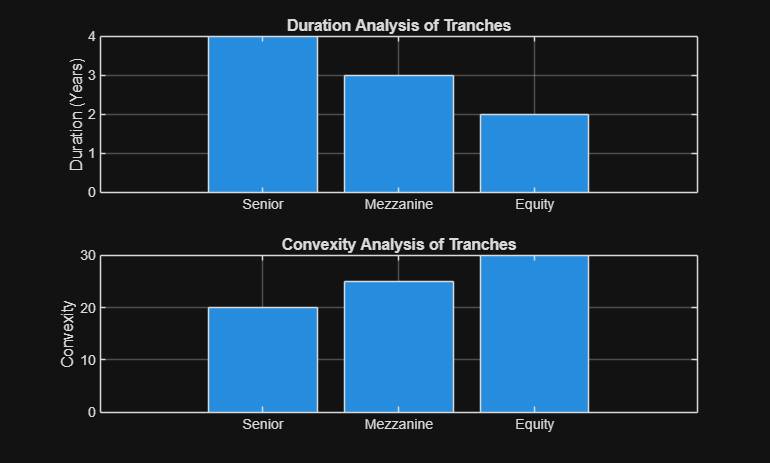

%% Chart 7: Duration and Convexity Analysis Charts
% For illustration, we use dummy data for duration and convexity of each tranche.
durations = [4, 3, 2];         % e.g., Senior=4 yrs, Mezzanine=3 yrs, Equity=2 yrs
convexities = [20, 25, 30];      % Dummy convexity numbers
figure;
subplot(2,1,1);
bar(durations);
set(gca, 'XTickLabel', tranche_names);
ylabel('Duration (Years)');
title('Duration Analysis of Tranches');
grid on;
subplot(2,1,2);
bar(convexities);
set(gca, 'XTickLabel', tranche_names);
ylabel('Convexity');
title('Convexity Analysis of Tranches');
grid on;

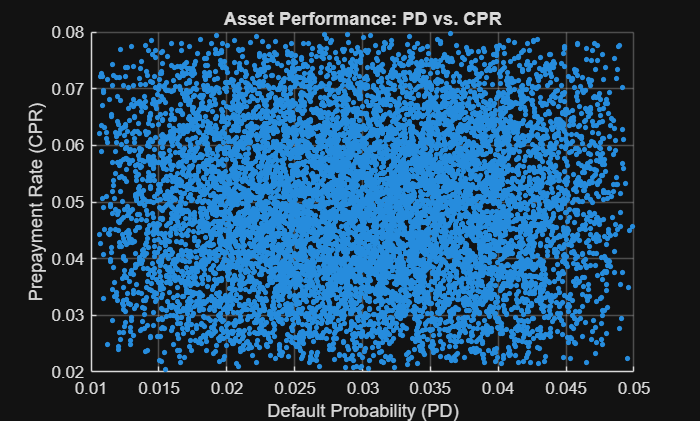

%% Chart 8: Asset/Collateral Performance Graph
% Scatter plot of PD vs. CPR from the tape simulation.
figure;
scatter(PD_tape, CPR_tape, 10, 'filled');
xlabel('Default Probability (PD)');
ylabel('Prepayment Rate (CPR)');
title('Asset Performance: PD vs. CPR');
grid on;

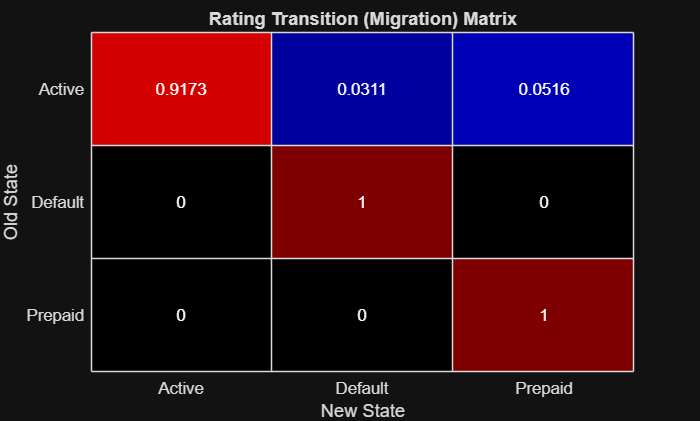

%% Chart 9: Rating Transition/Migration Heat Map
% Visualize the empirical transition matrix P_empirical as a heat map.
figure;
heatmap(P_empirical, 'XData',{'Active','Default','Prepaid'},'YData',{'Active','Default','Prepaid'});
cmap = jet(256);
cmap(1,:)=[0,0,0];
colormap(cmap);
colorbar off
title('Rating Transition (Migration) Matrix');
xlabel('New State');
ylabel('Old State');